clear
clc
close all

# MPEG LAYER II

### Read File:

file = 'project.wav';
[signal,Fs] = audioread(file);
file_info = audioinfo(file)

file_info = struct with fields:
             Filename: '/home/ozi/Desktop/MPEG-Audio-Compression/project.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240000
             Duration: 10
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


bps = file_info.BitsPerSample;
sound(signal,Fs);

### Get Filter Coefficients

num_filters= 32;
filter_order=512;
h_all = zeros(num_filters,filter_order);
h_coeffs = PQMF_ReadCoeffs();

L = 257

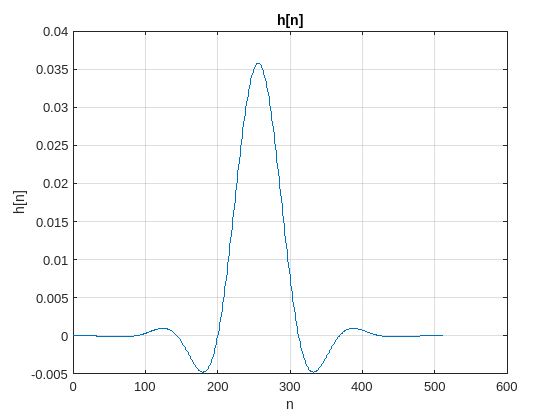

plot([0:512],h_coeffs)
grid on
title('h[n]')
xlabel('n')
ylabel('h[n]')

### Getting all modulated filters:

According to this equation:

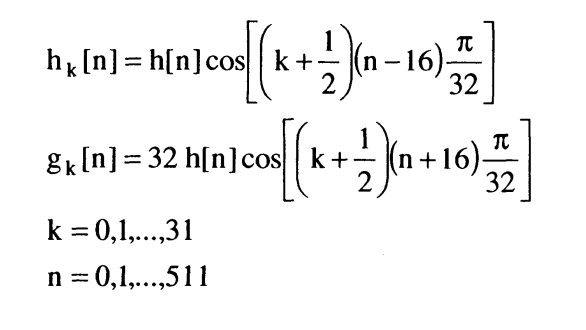

(Bosi, Goldberg, sect 4.2)

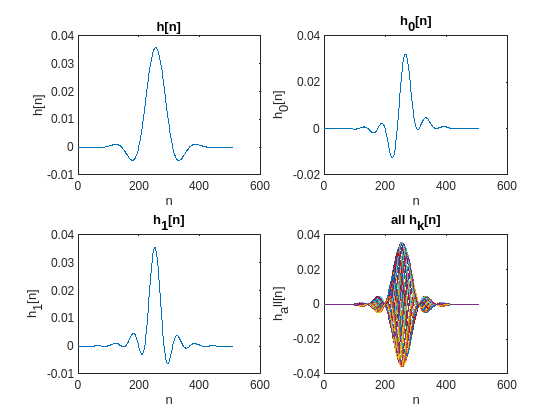

for k= 0 :num_filters-1
    for n=0: filter_order-1
        h_all(k+1,n+1) = h_coeffs(n+1) * cos((k+(1/2)*(n-16)*(pi/32)));
    end
end

subplot(2,2,1)
plot([0:511],h_coeffs(1:512))
title('h[n]')
xlabel('n')
ylabel('h[n]')
subplot(2,2,2)
plot([0:511],h_all(1,:))
title('h_0[n]')
xlabel('n')
ylabel('h_0[n]')
subplot(2,2,3)
plot([0:511],h_all(2,:))
title('h_1[n]')
xlabel('n')
ylabel('h_1[n]')
subplot(2,2,4)
plot([0:511],h_all)
title('all h_k[n]')
xlabel('n')
ylabel('h_all[n]')

### Now, Let's filter the signal:

sig_filtered =[];
for k=0:1:31
    sig_f= filter(h_all(k+1,:),1,signal);  %Filtering 
    sig_down = downsample(sig_f,32);       %Down Sampling
    sig_filtered=[sig_filtered sig_down];  %Appending
end

# `Psychoacoustic Model `

## `Computing SPL`

### Signal Spectrum after FFT

N = 1024;           % number of points
% load the Signal_Spectrum.mat
X = load('Signal_Spectrum.mat');
Signal_Spectrum = (X.Signal_Spectrum);
% set the freq vector for the signal
f_vector = linspace(-Fs/2,Fs/2,N);

% get the right half of the Spectrum
half_spectrum = X.Signal_Spectrum(513:end);
half_freq = f_vector(N/2+1:end);

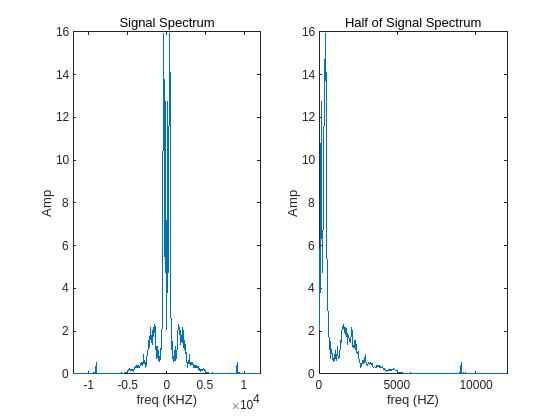

% plot the Signal Spectrum
figure(1);
subplot(1,2,2);
% the whole signal spectrum
subplot(1,2,1);
plot(f_vector,Signal_Spectrum)
xlabel('freq (KHZ)')
ylabel('Amp')
subtitle('Signal Spectrum')
% half Signal Spectrum
subplot(1,2,2);
plot(half_freq,half_spectrum);
xlabel('freq (HZ)');
ylabel('Amp');
subtitle('Half of Signal Spectrum');

### SPLs computing and evaluating

% Calculate the Lks for each value at half_spectrum
Lk = Lk_fn(N,half_spectrum);

% Calculate the threshold_in_quiet for each freq
q_threshold = threshold_in_quiet(half_freq);

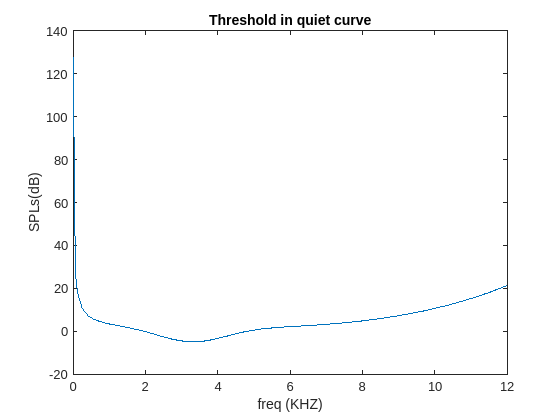

close all;
% plot threshold_in_quiet
plot(half_freq/1000,q_threshold);
title('Threshold in quiet curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

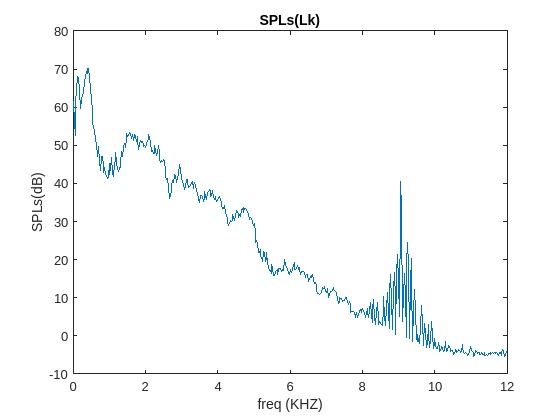

% plot Lks 
plot(half_freq/1000,Lk);
title('SPLs(Lk)');
xlabel('freq (KHZ)');
ylabel('SPLs(dB)');

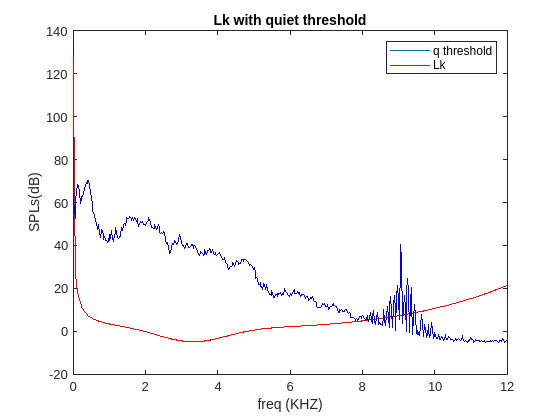

title('Lk with quiet threshold');
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q threshold','Lk'});
hold off

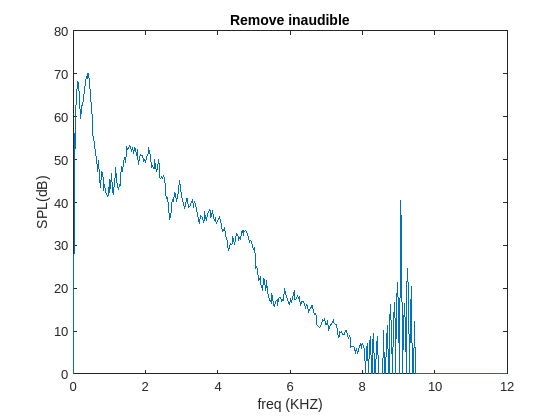

% set zeros to Lks that is less than the quite threshold
indices = q_threshold>Lk;
Lk(indices) = 0;
% plot
plot(half_freq/1000,Lk);
title('Remove inaudible')
xlabel('freq (KHZ)')
ylabel('SPL(dB)')

# `Psychoacoustic Model `

## Separation of Tonal & Non-Tonal Components

#### Divide the Lk specturm into 32 sub-bands 

% convert the SPLs and the freq into sub-bands
sub_num = 32;
SPL_matrix = vector2matrix(Lk,sub_num);
freq_matrix = vector2matrix(half_freq,sub_num);

#### Get the masker Masker frequencies

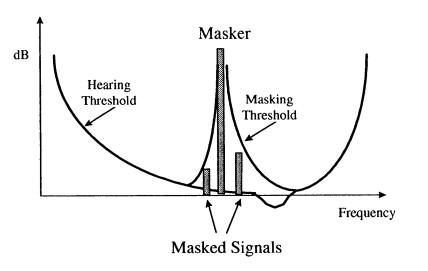

% Looping over the sub-bands
for i = 1 : sub_num

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%% Get the golobal and local maximas  %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % the SPL and the freq of the i sub-band
    sub_band_SPL  = SPL_matrix(i,:);
    sub_band_freq = freq_matrix(i,:);
    % get the golobal and local maximas 
    [peakValues, peakIndices] = Find_maximas(sub_band_SPL);     % peakValues is the spl value
                                                                % peakIndices is its position       
    
    % looping over the peaks in the sub-band
    for j = 1: length(peakValues)

        % set the masker freq and its SPL
        masker_freq = sub_band_freq(peakIndices(j));
        masker_SPL  = peakValues(j);

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%% The spread function for each maxima %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % check that SPL of the masker is not zero
        if masker_SPL ~= 0
            
            % calculate the most right freq affected by the masker
            f2 = masking_threshold(masker_SPL,masker_freq);
            % and its SPL
            f2_SPL = threshold_in_quiet(f2);
            % Two points to interp the spreading function
            y_spl  = [masker_SPL f2_SPL];          
            x_freq = [masker_freq f2];
            % p = spreading_fn(x,y);
            p = polyfit(x_freq,y_spl,1);
            delta = 1.5; 
            p = p*delta;
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %%%%%%%%%%%%%%% Masking the Non-Tonal Components for each sub-band %%%%%%%%%%%%%%%%%%%%%
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
            % looping over the affected part of the sub-band
            for k = peakIndices(j)+1 : 16
                if sub_band_freq(k) < f2
                    % get the masking threshold for tonal components
                    m_threshold = polyval(p,sub_band_freq(k));
                    if sub_band_SPL(k) < m_threshold
                        sub_band_SPL(k)=0;
                    end
                end
            end
            
        end
    end
    SPL_matrix(i,:) = sub_band_SPL;             % set the changes to the SPL_matrix
end

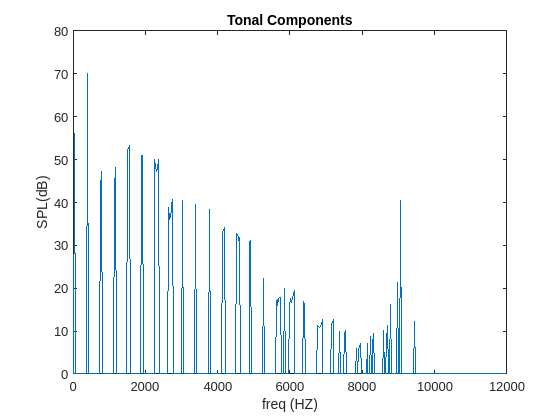

% get the vector of the Lks after the 
Lk_after_masking = matrix2vector(SPL_matrix);
% plot
plot(half_freq,Lk_after_masking);
title('Tonal Components');
xlabel('freq (HZ)');
ylabel('SPL(dB)');

### Decoder

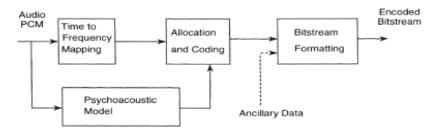

#### FFT to the Filter Bank Sub-bands

% get the FFT to the output of the filter bank
sig_filtered_matrix = sig_filtered.';       % Transpose of sig_filtered to make rows represent each sub-band 
sig_filtered_fft    = zeros(32,1024);       % Initialize the output of FFT to the sig_filtered 

% Apply FFT at each row (sub-band)
for i = 1:sub_num  
    sig_filtered_fft(i,:) = abs(fftshift(fft(sig_filtered_matrix(i,:),1024))); 
end

% get half the FFT output 
half_sig_filtered_fft = sig_filtered_fft(:,513:end);

#### Get the SPLs for each sub-band to mask out the undesired frequencies of the input data,

% calc the SPLs for each sub-band
SPLs_sig_filtered = Lk_fn(1024,half_sig_filtered_fft);

% apply masking
sig_filtered_masked = SPLs_sig_filtered.*Lk_after_masking;

### Bit allocation

% calc the sum of sub-bands SPLs
sum_spl = sum(sig_filtered_masked,2).';         
% bit allocation
BPS = file_info.BitsPerSample;                  % BitsPerSample from the audio info (16-bits)
sub_band_bits = bit_allocation(BPS,sum_spl);    % Apply the bit_allocation function
                                                % to get the num of bits for each sub-band

## Quantization

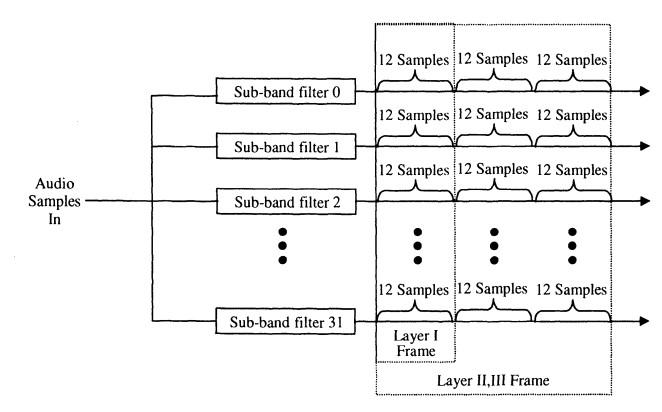


quantized_sig = [];                             % Initialize quantized_sig Vector
% looping over each 12 cols (frame)
for j = 1:12:size(sig_filtered_matrix,2)
    frame = [];                                 % Initialize empty Frame Vector
    % looping over each row (sub-band)
    for i = 1:size(sig_filtered_matrix,1)
        % Apply Quan function on each 12 sample and set its number of bits
        slice_12 = sig_filtered_matrix(i,j:j+12-1);                             % slice 12 samples              
        [maxi,mini,encoded_decimal] = Quan(slice_12,sub_band_bits(i));          % Apply Quan function
        encoded_binary = dec2bin(encoded_decimal,sub_band_bits(i));             % convert the Quan_sig decimal into binary                               
        granule = struct('max',maxi,'min',mini,'binary_code',encoded_binary);   % set max min binary_code into granule struct
        frame = [frame granule];                                                % append the granule to the frame
    end
    quantized_sig = [quantized_sig  frame];     % Append the frame to the quantized_sig
end

# `Decoder`

**De-Quantization**

dequantized_signal = [];

for i=1:length(quantized_sig)
    current_frame = quantized_sig(i);
    encoded_binary = current_frame.binary_code;
    decoded_granule = bin2dec(encoded_binary);
    bits_num = size(encoded_binary, 2);
    dequantized_frame = DeQuan(current_frame.max, current_frame.min, bits_num, decoded_granule+1);
    dequantized_signal = [dequantized_signal dequantized_frame];
end

**Reshaping**

decoded_subbands_matrix = [];
num_granules = length(dequantized_signal)/(size(sig_filtered_matrix,1)*12);

index = 1;
for i=1:num_granules
    col_granule = [];
    for j=1:32
        current_granule = dequantized_signal(index:index+11);
        col_granule = [col_granule;current_granule];
        index = index+12;
    end
    decoded_subbands_matrix = [decoded_subbands_matrix col_granule];
end

**Applying Synthesis Filters**

%constructing synthesis fitlers
K = 32;
N = 512;
g = zeros(K,N);

for k=0:K-1
    for n=0:N-1
        g(k + 1,n + 1) = 32 * h_coeffs(n + 1)*cos((k + 0.5)*(n + 16)*pi/32);
    end
end

%applying synthesis filter
decompressed_signal = zeros(1,size(decoded_subbands_matrix,1)*size(decoded_subbands_matrix,2));
for k=1:K
    rec_signal = upsample(decoded_subbands_matrix(k,:), 32);
    filtered_rec_signal = filter(g(k,:), 1, rec_signal);
    decompressed_signal = decompressed_signal + rec_signal;
end

sound(decompressed_signal,Fs);

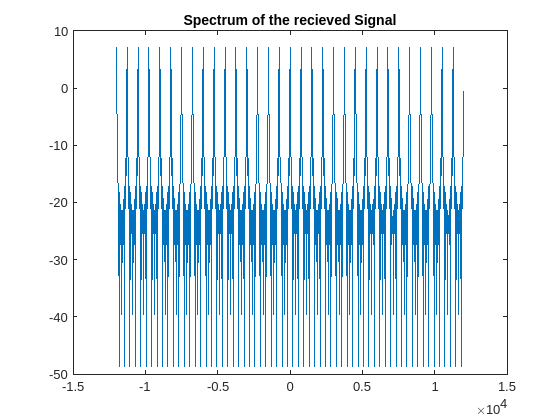

figure()
Signal_Spectrum_recieved = fftshift(fft(decompressed_signal , 1024));
freq = linspace(-Fs/2,Fs/2,length(Signal_Spectrum_recieved));
plot(freq, 20*log10(abs(Signal_Spectrum_recieved)));
title('Spectrum of the recieved Signal')